close all;% clear all;
% Local Host
load('C:\Paolo_Erazo\WorkspacePMS_Lafae\PMS_LafaeV0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\BESS_m.mat')
load('C:\Paolo_Erazo\WorkspacePMS_Lafae\PMS_LafaeV0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\Genset_m.mat')
load('C:\Paolo_Erazo\WorkspacePMS_Lafae\PMS_LafaeV0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\Grid_BRK_status.mat')
load('C:\Paolo_Erazo\WorkspacePMS_Lafae\PMS_LafaeV0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\Load_cmds_m.mat')
load('C:\Paolo_Erazo\WorkspacePMS_Lafae\PMS_LafaeV0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\CS_m.mat')
% %% Local host
% load('C:\Users\lafae\OPAL-RT\Lafae_PMS\MG_Lafae_V0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\BESS_m.mat')
% load('C:\Users\lafae\OPAL-RT\Lafae_PMS\MG_Lafae_V0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\GEN_m.mat')
% load('C:\Users\lafae\OPAL-RT\Lafae_PMS\MG_Lafae_V0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\Grid_BRK_status.mat')
% load('C:\Users\lafae\OPAL-RT\Lafae_PMS\MG_Lafae_V0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\Load_grid_m.mat')
% load('C:\Users\lafae\OPAL-RT\Lafae_PMS\MG_Lafae_V0\models\MG_Lafae\mg_lafae_sm_master\OpNTtarget\CS_m.mat')
%
%% Simulator 2
% load('C:\Paolo_Erazo\TotalEnergies\Modbus\Test_Modbus_Slave\Test_Modbus\models\Simulink\modbus_slave_sm_modbus_slave\OpREDHAWKtarget\BESS_m.mat')
% load('C:\Paolo_Erazo\TotalEnergies\Modbus\Test_Modbus_Slave\Test_Modbus\models\Simulink\modbus_slave_sm_modbus_slave\OpREDHAWKtarget\GEN_m.mat')
% load('C:\Paolo_Erazo\TotalEnergies\Modbus\Test_Modbus_Slave\Test_Modbus\models\Simulink\modbus_slave_sm_modbus_slave\OpREDHAWKtarget\Grid_BRK_status.mat')
% load('C:\Paolo_Erazo\TotalEnergies\Modbus\Test_Modbus_Slave\Test_Modbus\models\Simulink\modbus_slave_sm_modbus_slave\OpREDHAWKtarget\Load_grid_m.mat')
% load('C:\Paolo_Erazo\TotalEnergies\Modbus\Test_Modbus_Slave\Test_Modbus\models\Simulink\modbus_slave_sm_modbus_slave\OpREDHAWKtarget\CS_m.mat')


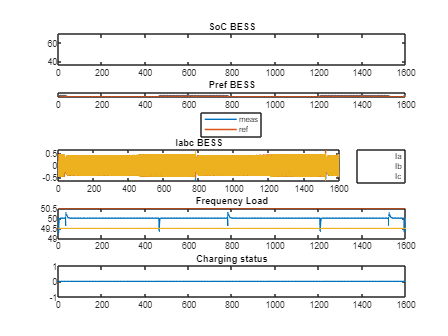


freq_max = 50.5*ones(1,length(Load_cmds(8,:)));
freq_min = 49.5*ones(1,length(Load_cmds(8,:)));
Power_peak = 7500*ones(1,length(Load_cmds(8,:)));
Power_peak2 = 6500*ones(1,length(Load_cmds(8,:)));
% BESS
a1 = figure(1);
subplot(5,1,1)
plot(BESS(1,:),BESS(2,:))
title('SoC BESS')
subplot(5,1,2)
plot(BESS(1,:),BESS(13,:))
title('Pref BESS')
ylabel('(pu)')
hold on;
plot(BESS(1,:),BESS(21,:))
legStr = { 'meas', 'ref'};
legend( legStr, 'location', 'southoutside' );
ylim([-0.5 3])
subplot(5,1,3)
plot(BESS(1,:),BESS(8,:))
title('Iabc BESS')
hold on;
plot(BESS(1,:),BESS(9,:))
plot(BESS(1,:),BESS(10,:))
legStr = { 'Ia', 'Ib','Ic'};
legend( legStr, 'location', 'eastoutside' );
subplot(5,1,4)
plot(Load_cmds(1,:),Load_cmds(8,:))
title('Frequency Load')
hold on;
plot(Load_cmds(1,:),freq_max)
plot(Load_cmds(1,:),freq_min)
hold off;
subplot(5,1,5)
plot(Load_cmds(1,:),Load_cmds(29,:))
title('Charging status')

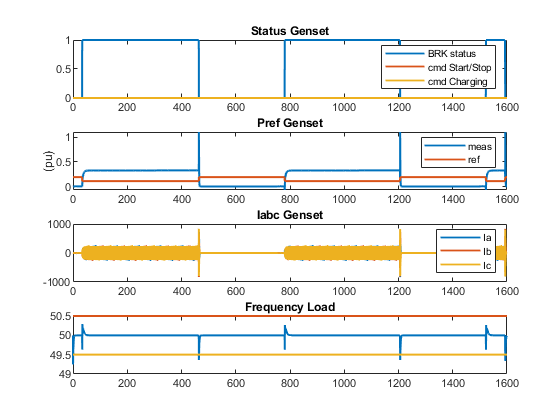

%print(a1,'-dpng','-r1200','Figures\BESS_m')

%% Genset
a2 = figure(2);
subplot(4,1,1)
plot(Genset(1,:),Genset(30,:))
title('Status Genset')
hold on;
plot(Load_cmds(1,:),Load_cmds(21,:))
plot(Load_cmds(1,:),Load_cmds(29,:))
legend('BRK status', 'cmd Start/Stop','cmd Charging')
hold off;
subplot(4,1,2)
plot(Genset(1,:),(Genset(11,:)/(1e3*5.96e3)))
title('Pref Genset')
ylabel('(pu)')
hold on;
plot(Genset(1,:),Genset(36,:)*10)
legend('meas','ref')
subplot(4,1,3)
plot(Genset(1,:),Genset(7,:))
title('Iabc Genset')
hold on;
plot(Genset(1,:),Genset(8,:))
plot(Genset(1,:),Genset(9,:))
legend('Ia','Ib','Ic')
subplot(4,1,4)
plot(Load_cmds(1,:),Load_cmds(8,:))
title('Frequency Load')
hold on;
plot(Load_cmds(1,:),freq_max)
plot(Load_cmds(1,:),freq_min)
hold off;

%print(a2,'-dpng','-r1200','Figures\Genset_m')

%% Load
set(groot,'defaultLineLineWidth',1.4)
% Plot Corrente Iabc
a3 = figure('WindowState','maximized')

a3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


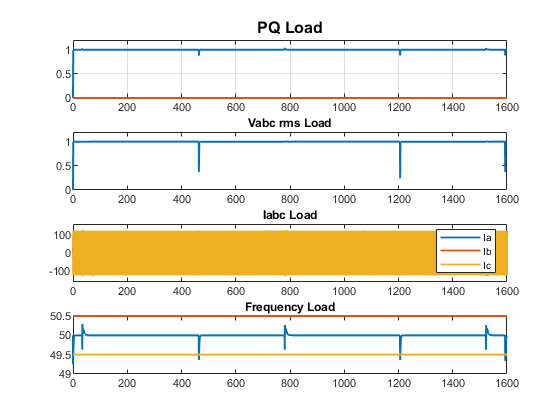

subplot(4,1,1)
plot(Load_cmds(1,:),Load_cmds(2,:)/1e3)
hold on;
grid on;
plot(Load_cmds(1,:),Load_cmds(3,:))
title('PQ Load','FontSize',12)
hold off
ylim([0 1.2])
subplot(4,1,2)
plot(Load_cmds(1,:),Load_cmds(4,:))
title('Vabc rms Load')
ylim([0 1.2])
subplot(4,1,3)
plot(Load_cmds(1,:),Load_cmds(5,:))
hold on;
plot(Load_cmds(1,:),Load_cmds(6,:))
plot(Load_cmds(1,:),Load_cmds(7,:))
title('Iabc Load')
legend('Ia','Ib','Ic')
ylim([-160 160])
hold off;
subplot(4,1,4)
plot(Load_cmds(1,:),Load_cmds(8,:))
title('Frequency Load')
hold on;
plot(Load_cmds(1,:),freq_max)
plot(Load_cmds(1,:),freq_min)
hold off;

%print(a3,'-dpng','-r1200','Figures\Load')


## Comparation


set(groot,'defaultLineLineWidth',1.4)
a4 = figure('WindowState','maximized')

a4 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


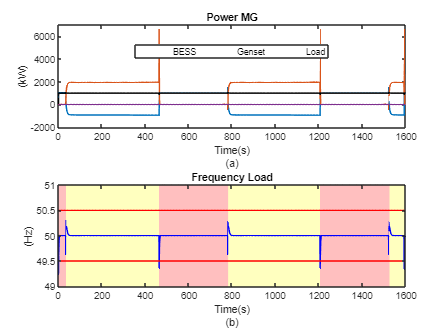

subplot(2,1,1)
plot(BESS(1,:),BESS(13,:)*2.2e3)
hold on;
plot(Genset(1,:),(Genset(11,:)/(1e3)))
plot(Load_cmds(1,:),Load_cmds(2,:),'k')
plot(Grid_BRK_status(1,:),Grid_BRK_status(2,:))
%plot(Grid_BRK_status(1,:),Power_peak)
title('Power MG')
ylabel('(kW)')
xlabel({'Time(s)','(a)'})
hold off
legStr = {'BESS','Genset', 'Load'};
legend( legStr, 'orientation', 'horizontal','location', 'best' );
ylim([-2000 7000])
hold on;
%area(linspace(0, 34.78),linspace(-2000, 7000),"FaceColor","r","FaceAlpha",0.25)
subplot(2,1,2)
area(linspace(0, 34.78),linspace(61, 61),"FaceColor","r","FaceAlpha",0.25)
hold on;
area(linspace(34.781, 463.34),linspace(61, 61),"FaceColor","y","FaceAlpha",0.25)
area(linspace(463.34, 781.98),linspace(61, 61),"FaceColor","r","FaceAlpha",0.25)
area(linspace(781.98, 1205.55),linspace(61, 61),"FaceColor","y","FaceAlpha",0.25)
area(linspace(1205.55, 1525.72),linspace(61, 61),"FaceColor","r","FaceAlpha",0.25)
area(linspace(1525.72, 1600),linspace(61, 61),"FaceColor","y","FaceAlpha",0.25)
plot(Load_cmds(1,:),Load_cmds(8,:),'b')
title('Frequency Load')
ylabel('(Hz)')
xlabel({'Time(s)','(b)'})
ylim([49 51])
hold on;
plot(Load_cmds(1,:),freq_max,'r')
plot(Load_cmds(1,:),freq_min,'r')
hold off;
hold on;


set(groot,'defaultLineLineWidth',1.4)
a5 = figure('WindowState','maximized')

a5 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


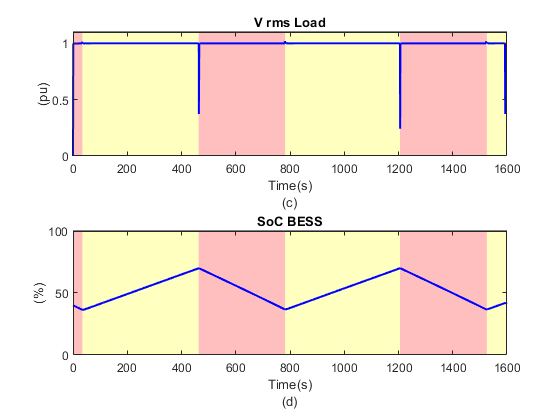

subplot(2,1,1)
area(linspace(0, 34.78),linspace(1.1, 1.1),"FaceColor","r","FaceAlpha",0.25)
hold on;
area(linspace(34.781, 463.34),linspace(1.1, 1.1),"FaceColor","y","FaceAlpha",0.25)
area(linspace(463.34, 781.98),linspace(1.1, 1.1),"FaceColor","r","FaceAlpha",0.25)
area(linspace(781.98, 1205.55),linspace(1.1, 1.1),"FaceColor","y","FaceAlpha",0.25)
area(linspace(1205.55, 1525.72),linspace(1.1, 1.1),"FaceColor","r","FaceAlpha",0.25)
area(linspace(1525.72, 1600),linspace(1.1, 1.1),"FaceColor","y","FaceAlpha",0.25)
plot(Load_cmds(1,:),Load_cmds(4,:),'b')
title('V rms Load')
ylabel('(pu)')
xlabel({'Time(s)','(c)'})
ylim([0 1.1])
subplot(2,1,2)
area(linspace(0, 34.78),linspace(100, 100),"FaceColor","r","FaceAlpha",0.25)
hold on;
area(linspace(34.781, 463.34),linspace(100, 100),"FaceColor","y","FaceAlpha",0.25)
area(linspace(463.34, 781.98),linspace(100, 100),"FaceColor","r","FaceAlpha",0.25)
area(linspace(781.98, 1205.55),linspace(100, 100),"FaceColor","y","FaceAlpha",0.25)
area(linspace(1205.55, 1525.72),linspace(100, 100),"FaceColor","r","FaceAlpha",0.25)
area(linspace(1525.72, 1600),linspace(100, 100),"FaceColor","y","FaceAlpha",0.25)
plot(BESS(1,:),BESS(2,:),'b')
title('SoC BESS')
ylim([0 100])
ylabel('(%)')
xlabel({'Time(s)','(d)'})

print(a1,'-depsc','-r1200','Figures\PV_Iabc')
